# Prototype

Tadiwos created some example code in `DIP_2_with_Graph`, which serves as the basis for the rest of my code.

For this entire research project, we have used the 119th frame of Video 6, Chunk 1 (the 269th frame of the video overall) as the starting point. The reason for this choice is that noticeable movement begins at this frame. This made testing new methods much easier since we didn’t have to generate a bunch of frames where we were essentially standing still at the beginning.

Here is a link to all video's that were created: [Google Drive](https://drive.google.com/file/d/1HySCHfZUpBvAJmShDPezG1w1hhJe5emD/view?usp=drive_link)

in case the link doesn't work: [https://drive.google.com/file/d/1HySCHfZUpBvAJmShDPezG1w1hhJe5emD/view?usp=drive_link](https://drive.google.com/file/d/1HySCHfZUpBvAJmShDPezG1w1hhJe5emD/view?usp=drive_link)

You can download these vids and put them in the Videos folder if you want. Or watch them in the drive.

chunck1 = load("Imports\Ballenwerper_sync_380fps_006_chunk_1.mat"); % you may have to change your Matlab's Current Folder
frame1 = squeeze(chunck1.video_data(1, :, :));

A manually created mask was also made to identify the movable parts of the machine.

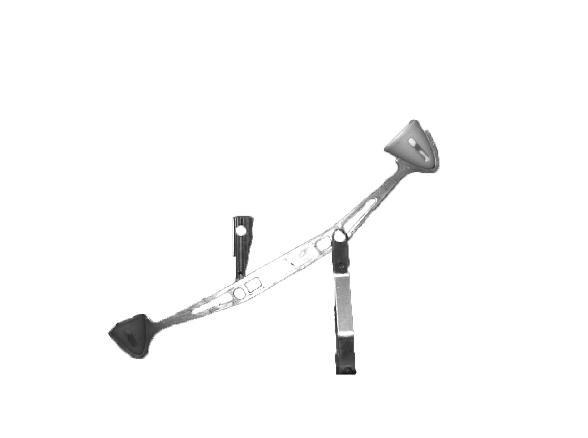

image = imread('trail.png');
imshow(image);

The image was then edited to improve edge detection.

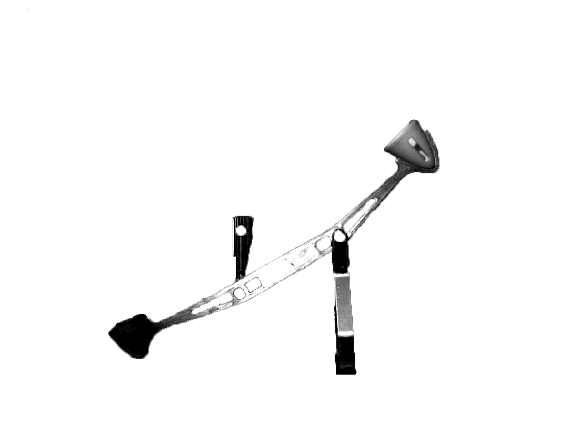

image_gray = rgb2gray(image);
image_gray = imadjust(image_gray); % Adjust contrast
image_gray = medfilt2(image_gray, [3 3]); % Apply median filter
imshow(image_gray);

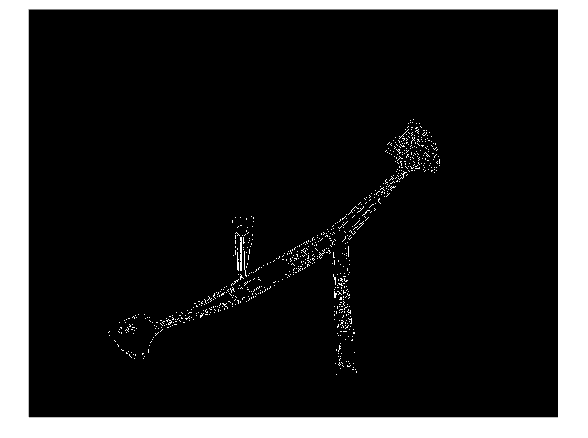


image_gray_edge = edge(image_gray, 'canny');
imshow(image_gray_edge);

This edge detection was then used to find Harris Features, which will serve as the points we aim to track.

points = detectHarrisFeatures(image_gray_edge);

tracker = vision.PointTracker('MaxBidirectionalError', 3);
initialize(tracker, points.Location, frame1);

Since we are only focused on tracking all the points here, I won’t go into detail about the parts of the code that deal with what happens to the data generated by the points. That will be covered in the other reports.

We then use the tracker in a straightforward way.

for i = 119:150
    % Extract the next frame
    nextFrame = squeeze(chunck1.video_data(i, :, :));

    % Track points
    [newPoints, validity] = tracker(nextFrame);
    validNewPoints = newPoints(validity, :);
end

which results in this.

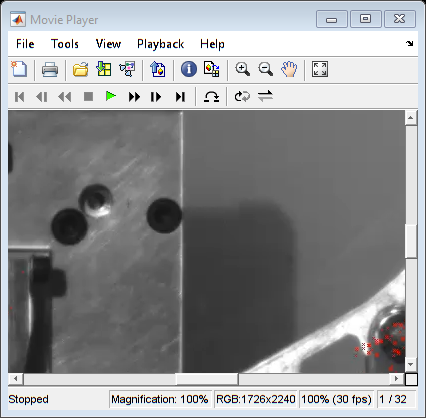

implay("Videos\OriginalTracking.mp4", 30);

This is a good start. If run this over the whole video:

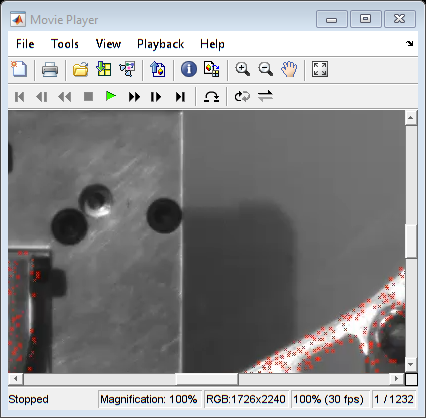

%Code to make the video, comment out to spare time when pressing run.

% clearvars -except Video_6;
% load_video_chunks([6], true); %loads video 6 and deletes the chunks from memory when the video is made
% 
% 
% image = imread('trail.png');
% 
% frame1 = squeeze(Video_6(119+150, :, :));
% 
% image_gray = rgb2gray(image);
% image_gray = imadjust(image_gray); % Adjust contrast
% image_gray = medfilt2(image_gray, [3 3]); % Apply median filter
% imshow(image_gray);
% 
% image_gray_edge = edge(image_gray, 'canny');
% points = detectHarrisFeatures(image_gray_edge);
% tracker = vision.PointTracker('MaxBidirectionalError', 3);
% initialize(tracker, points.Location, frame1);
% 
% outputVideo = VideoWriter("FullOriginalTracking.mp4", 'MPEG-4');
% outputVideo.FrameRate = 30;
% open(outputVideo);
% 
% for i = (119+150):1500
%     % Extract the next frame
%     nextFrame = squeeze(Video_6(i, :, :));
% 
%     % Track points
%     [newPoints, validity] = tracker(nextFrame);
%     validNewPoints = newPoints(validity, :);
% 
%     thisFrameRGB = repmat(uint8(nextFrame), [1, 1, 3]); % Convert to RGB
%     thisFrameRGB = insertMarker(thisFrameRGB, validNewPoints, 'x', 'Color', 'red', 'Size', 1);
% 
%     writeVideo(outputVideo, thisFrameRGB);
% end
% 
% close(outputVideo);

implay("Videos\FullOriginalTracking.mp4", 30);

We don’t start with many points, and we lose a significant number of them as we progress.

Our goals are:

- Detecting the entire contraption's movements.

- Keeping the dots consistent (e.g., avoiding drifting when standing still).

The reason for this is that, if we can track all the points, we could measure things like deformation or similarities between runs with a very high degree of accuracy. While this level of precision isn’t strictly necessary—as you can see in the other report, our teams were able to work effectively with singular points—it would allow us to create a more detailed image of deformations and related phenomena. Having all the points available provides a much finer level of detail.

To achieve this, a new folder with a new script was created: the "TrackingWholeObject" directory, with "BY_TrackingPoints" serving as the main script.

# Main Script

This script explored various tools and methods to create a video that visually demonstrates all the points of the object being tracked.

## 1) getting more points

First things first: we want more points to track. The goal is to obtain as many as possible. The first approach we tried involved using multiple edge detection methods and layering them.

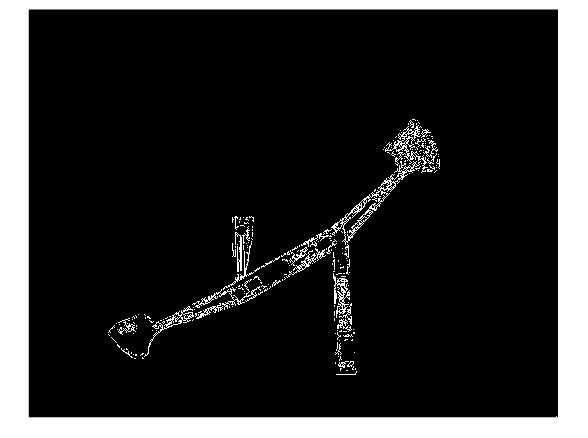

image = imread('trail.png');
image_gray = rgb2gray(image);
image_gray = imadjust(image_gray);
image_gray = medfilt2(image_gray, [3 3]);

SobelMask       = edge(image_gray, 'Sobel');
PrewittMask     = edge(image_gray, 'Prewitt');
RobertsMask     = edge(image_gray, 'Roberts');
CannyMask       = edge(image_gray, 'Canny');
ApproxCannyMask = edge(image_gray, 'approxcanny');
LogMask         = edge(image_gray, 'log');
ZeroCrossMask   = edge(image_gray, 'zerocross');

Total = SobelMask | PrewittMask | RobertsMask | CannyMask | ApproxCannyMask | LogMask | ZeroCrossMask;
imshow(Total);


implay("Videos\MoreEdges.mp4", 30);

This approach does allow more features to be found, resulting in more points to track in the video.

However, we still wanted more. Ideally, every pixel should be a trackable point. Then we realized that, since we already have the cutout of the starting frame, there’s no need for all this edge detection. We can simply make every pixel a point

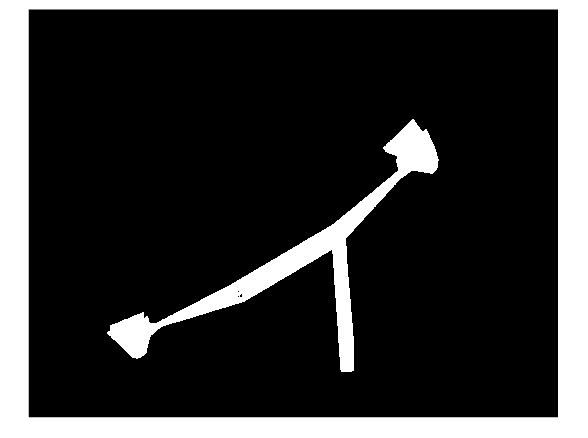

image_gray = imread('cutout.png');
binaryImage = imbinarize(image_gray, 0.1);
imshow(binaryImage);

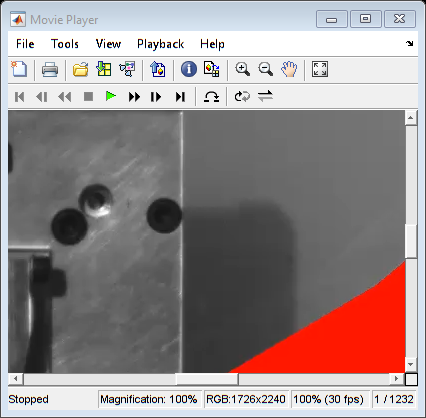


[y, x] = find(binaryImage);
points = [x, y];

implay("Videos\FirstFullMask.mp4", 30);

This method creates many more points we can track. However, there are still a few problems:

- Points disappear.

- Points glide over the object itself, with some even oscillating in place.

- Some points start getting lost in the background, attaching to areas we don’t want to track.

We assumed that much of this was caused by flickering lights and the lack of contrast in the image. Addressing these issues became our next focus.

## 2) Lighting

The two main lighting issue are the bad contrast, and the flickering of the lights. First thing we focused on was increasing the contrast. 

### 2.1) Contrast

To address this, we first tried imadjust.

clearvars -except Video_6;
load_video_chunks([6], true);

Skipping Video_6: Already loaded.


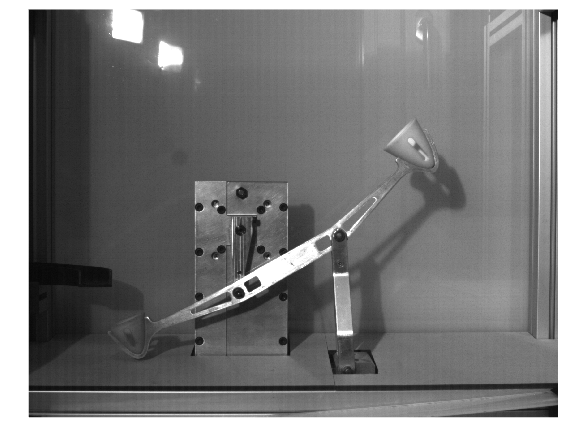


exampleFrame = squeeze(Video_6(119+150, :, :));
imshow(exampleFrame);

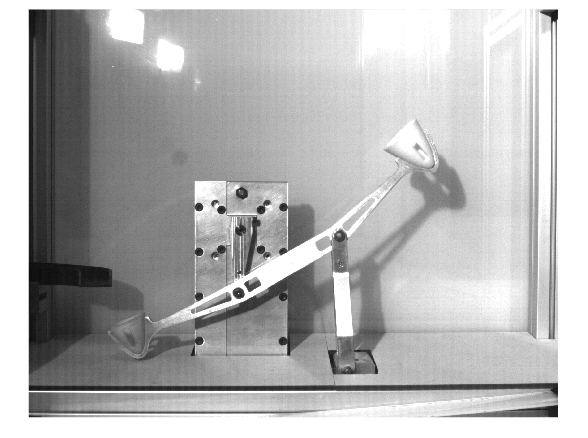


imshow(imadjust(exampleFrame, [0, 0.6]));

Finding nice value's was a bit finacky, so next we explored histogram equalization using the MATLAB function `histeq`.

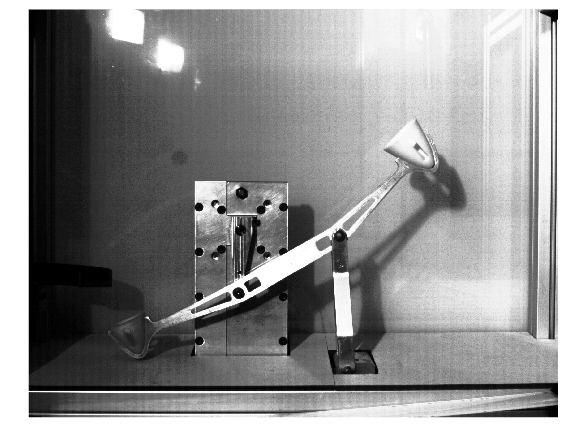

imshow(histeq(exampleFrame));

This approach improved the frame quality somwhat but a good imadjust was still better. 

Then we discovered `adapthisteq`, which is essentially `histeq` applied over smaller tiles throughout the image. This produced results like this:

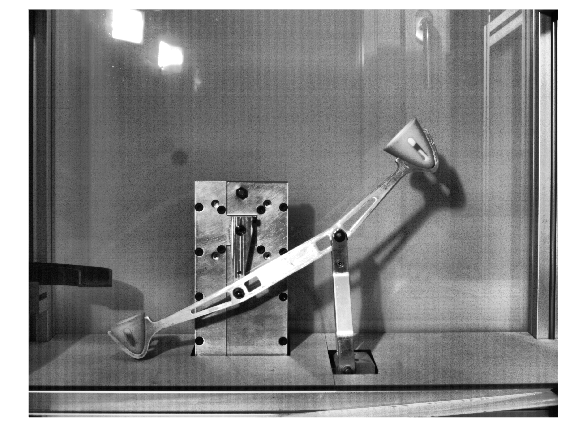

imshow(adapthisteq(exampleFrame));

This was the best we found. The shadows on the left mostly dissapeared. So we used this is to bake the contracst better in each frame. 

### 2.2) Flickering

The next issue was fixing the flickering. We initially thought that enhancing the contrast of all frames might resolve the problem, but after processing a few frames, it became clear this wasn’t the case. We needed a more fundamental solution to address the issue.

Then we came up with an idea: there are areas in the video that don’t move, so their brightness should remain consistent throughout the video. For example, the first few rows of the frame remain static.

Using this idea, we calculated the average brightness of these static pixels in the reference frame. For each subsequent frame, we adjusted the overall brightness by the amount needed to make these same pixels match the brightness of the reference frame.

%before we start looping through frames

% refranceFrame = squeeze(Video_6(1, :, :));
% 
% topRows = 1:30;
% referenceBrightness = mean(refranceFrame(topRows, :), 'all');
% 
% % processingLoop
% for i = (119+150):1500
%     thisFrameNotNormal = squeeze(Video_6(i, :, :));
% 
%     nextFrame = adapthisteq(thisFrameNotNormal, "Distribution", "exponential");
% 
%     % Normalize lighting using top rows
%     currentBrightness = mean(nextFrame(topRows, :), 'all'); %mean brightes of top pixles
%     adjustmentFactor = referenceBrightness / currentBrightness;
%     nextFrame = nextFrame * adjustmentFactor;
%     normilzedFrame = min(nextFrame, 255); % Clip to valid range
% 
%     %This was made into a funtion, so the real code it would look like:
%     %normilzedFrame = normalizeFrame(thisFrameNotNormal, referenceBrightness);
% 
%     fprintf("Current Brightness: %.3f, Reference Brightness: %.3f, Adjustment Factor: %.3f\n", currentBrightness, referenceBrightness, adjustmentFactor);
% end

implay("Videos\topframes.mp4", 30);

The reference frame was initially set as the very first frame. Later, it was changed to a frame with the median brightness of all frames. This adjustment ensured that the reference brightness was closer to the average brightness of most frames, improving the overall consistency.

More information about the median brightness frame can be found in the "background" section.

Using this in a full vide you get this:

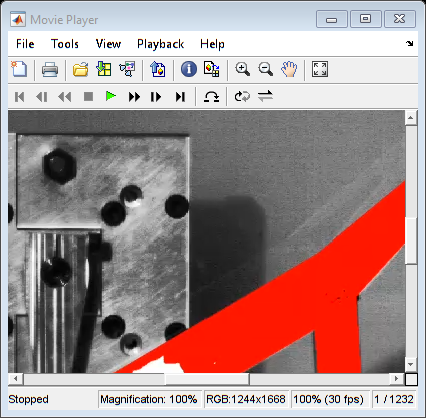

implay("Videos\NoFlickerAndFullMAsk.mp4", 30);

While this is an improvement. It's still not what we really want in the end. The oscaltion of random points has lessend a lot. And we have less points that dissapear. Still though, we lose a lot.

## 3) regenerating lost points

Since we kept losing points. We needed a way to create new ones. To correct for the points we were losing. So, while we may have lost some of points we were tracking from one frame to the other, what we still have is the frame itself, and remaining points. So, the idea was, using both of them, to recreate the points we lost, and keep tracking the hole object this way. 

### 3.1) vision.ForegroundDetector

First thing we looked into after some googling was the "vision.ForegroundDetector". It's a matlab tool that's suppose do what it says. It's the most simple soltion, but it did not work. A lot of time was spend on trying to make this work since it's the easiest solution. The main issue was, it needs training data. At first we assume this was just the video itself. But after some googling, we learned that the training data needs to consit of only background images as the frame. Something that was not clear to us from the matlab help documention. We didn't have a background image. We did try to make one though. 

The file "creatingBackgroundImageOfVideo.m" is used to grab the mean of the all the pixles values of the frames with the most movement in the video. This creates this result

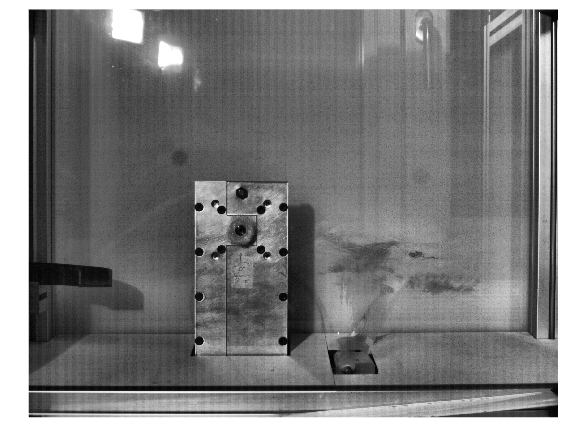

imshow("median_image_filtered.png");

This is a pretty good start. But the right side still has a lot of bad pixles. So a second script was made. "manualEditBackground" was used to get rid of some of the imperfections. The way this one works is that a few frames were manualy selected because the machine moved a lot. Then the background is manualy selected by the user as well using "roipoly" and the mean value's get calculated of those selected pixles at the end. They then replace the pixles in the previous image. The result is a better background image.

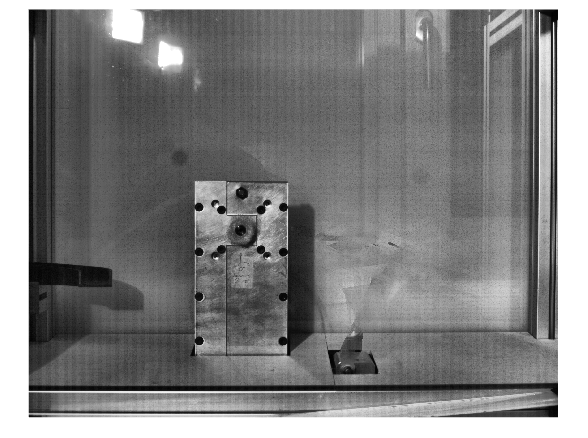

imshow("updated_background.png");

We tried using this with the "vision.ForegroundDetector" again to weird and inconsistent results. So, decding we didn't understand that tool enough. We dropped it.

This code was later used again in the function "getAreaOfIntrest.m".

### 3.2) Area Of Intrest

using the background we can now at least narrow down the search of the area in the image we need to look for new points in. Most of the edge detection algorrthyems and the like will detected other things in the background as well. Like the light and it's reflection in the background. So, we can make a very general area we call the "Area Of Intrest". This i s suppose to be very aproximatmy all the moving parts of the image. 

clearvars -except Video_6;
load_video_chunks([6], true);

Skipping Video_6: Already loaded.


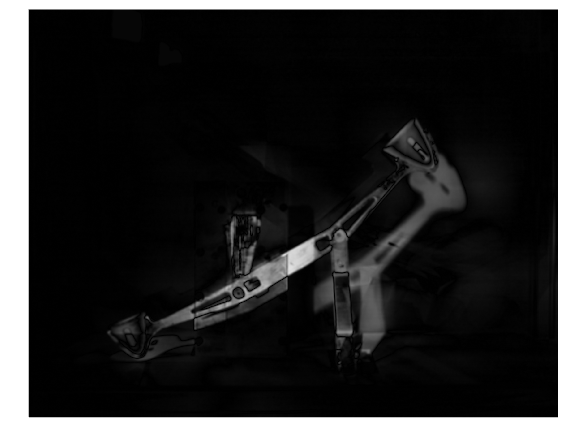


backGround = imread("updated_background.png");
frame = squeeze(Video_6(269, :, :));

topRows = 1:30;
referenceBrightness = mean(backGround(topRows, :), 'all');
frame = normalizeFrame(frame, referenceBrightness);

%make filter the frame a bit to make the impact of the imperfact background
%image less
kernel = fspecial('average', [10, 10]);
backGround = imfilter(backGround, kernel, 'replicate');
frame = imfilter(frame, kernel, 'replicate');

diffResult = imabsdiff(backGround, frame);

imshow(diffResult);

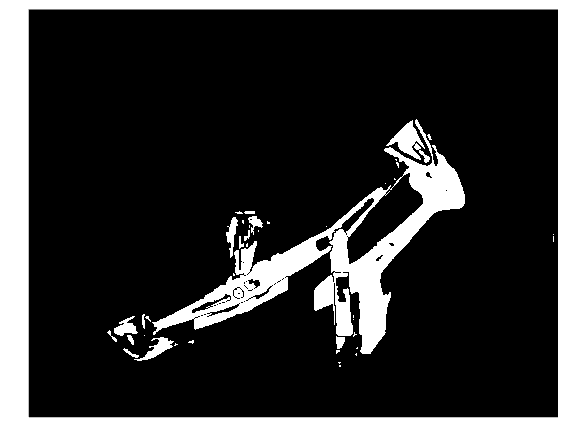


binVersion = imbinarize(diffResult, 0.12);
imshow(binVersion);

This is a great start. It shows a lot of things we want. There are still a few issues though.

- because some part of the machine hace similiar colors as th ebackground, they got filtered out with the imabsdiff. 

- because the shadows also move, they have also been selected.

to fix thise, we do two things. First we fill up much of the lost area. Because Area of intrest is meant to be rather broad starting point. We can dilate rather genurasly

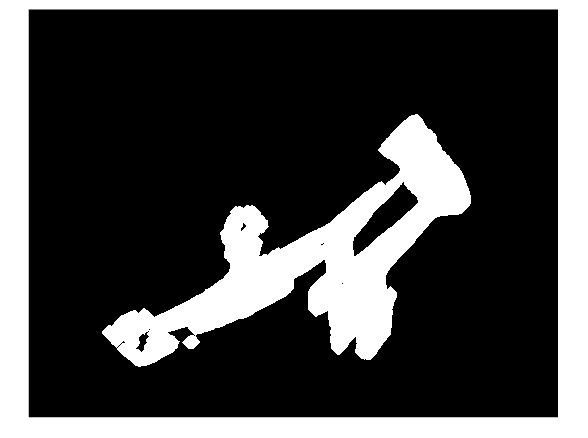

noDots = bwareaopen(binVersion, 200);
areaOfIntrestWithShadows = imdilate(noDots, strel('line', 35, 45));
areaOfIntrestWithShadows = imdilate(areaOfIntrestWithShadows, strel('line', 35, -45));
imshow(areaOfIntrestWithShadows);

Afterwards, we take the adaptive binary mask of the frame, so we can get rid of the shadows.

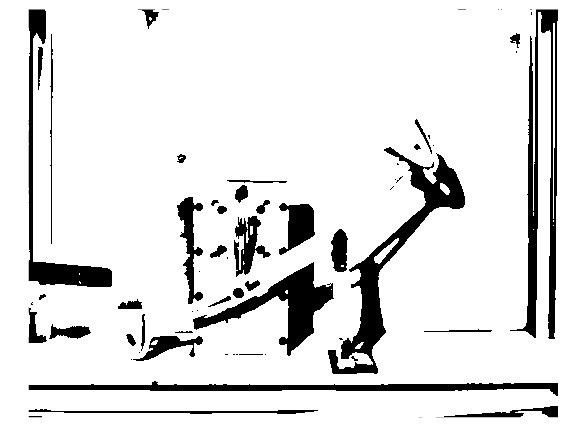

binFrameWithNoShadows = imbinarize(frame, 'adaptive', 'Sensitivity', 0.9);
imshow(binFrameWithNoShadows);

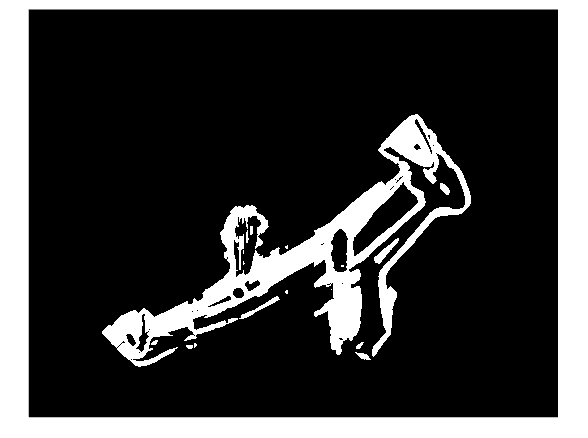


areaOfIntrestWithHoles = binFrameWithNoShadows & areaOfIntrestWithShadows;
imshow(areaOfIntrestWithHoles);

This doesn't fully get rid fof the shadows. But it does make this a lot better. Then we do some final touches to the frame so it's not full of holes and floating places.

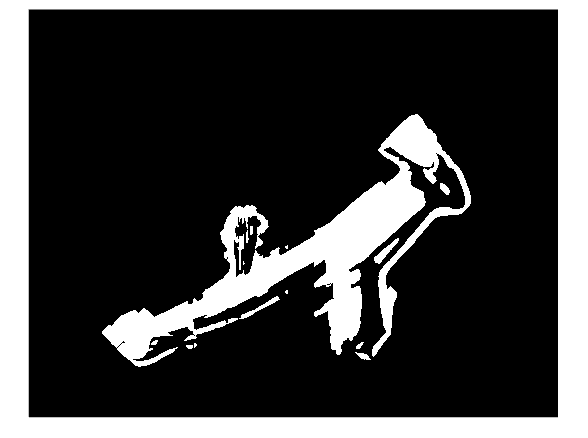

areaOfIntrestFilled = imfill(areaOfIntrestWithHoles, 'holes');
areaOfIntrest = bwareaopen(areaOfIntrestFilled, 100);
imshow(areaOfIntrest);

This gives us a good starting shape.

### 3.3) creating the regions

Next, we need to carve out the regions from this mask. This is done in a few ways. We start by turning the valid points we tracked into a binary mask.

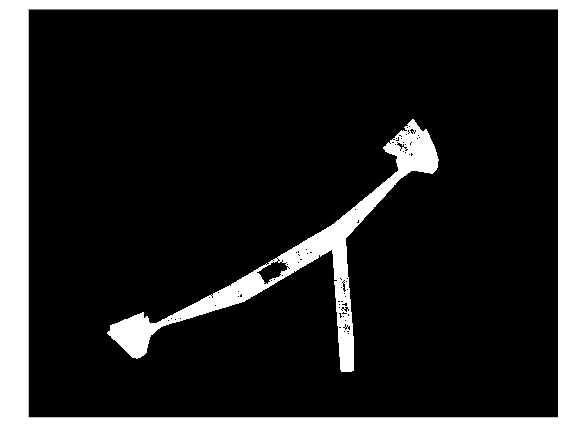

% real code
%[newPoints, validity] = tracker(thisFrame);
%validNewPoints = newPoints(validity, :);
frame = squeeze(Video_6(269, :, :));

%to make this rapport easier I will be doing this instead
validNewPoints = load('validNewPoints.mat');
validNewPoints = validNewPoints.validNewPoints;

% we turn these points into a binary mask
validNewPointsBinaryMask = false(size(frame)); % Initialize a binary mask of the same size as the frame

rows = round(validNewPoints(:, 2)); % Y-coordinates 
cols = round(validNewPoints(:, 1)); % X-coordinates
% Set the corresponding locations in the mask to true
validNewPointsBinaryMask(sub2ind(size(validNewPointsBinaryMask), rows, cols)) = true;
imshow(validNewPointsBinaryMask);

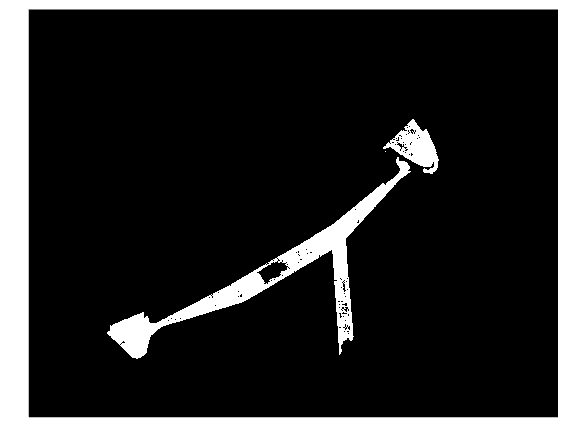


%only use the points that are in the areaOfIntrest
validNewPointsBinaryMask = validNewPointsBinaryMask & areaOfIntrest;
imshow(validNewPointsBinaryMask);

#### 3.3.1) edge detection

We then looked into edge detection. Combined multiple edge detection algorithms (`Sobel`, `Prewitt`, `Roberts`, `Canny`, and `ApproxCanny`) to create a comprehensive edge map. These edges served as potential regions for redistributing points. zerocross and log weren't used because they created to much noise.

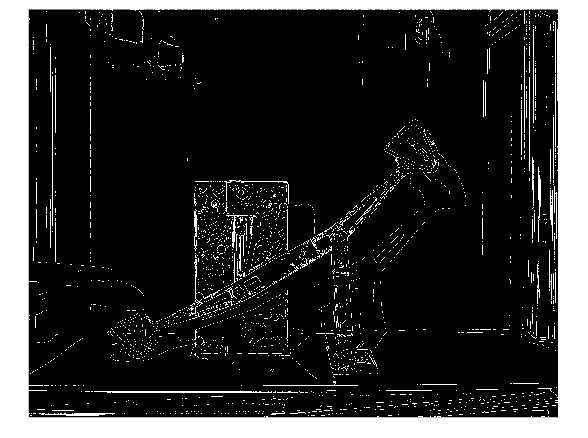

frame = squeeze(Video_6(269, :, :));


SobelMask       = edge(frame, 'Sobel');
PrewittMask     = edge(frame, 'Prewitt');
RobertsMask     = edge(frame, 'Roberts');
CannyMask       = edge(frame, 'Canny', [], 4); %more lines less noise

total = SobelMask | PrewittMask | RobertsMask | CannyMask;

imshow(total);

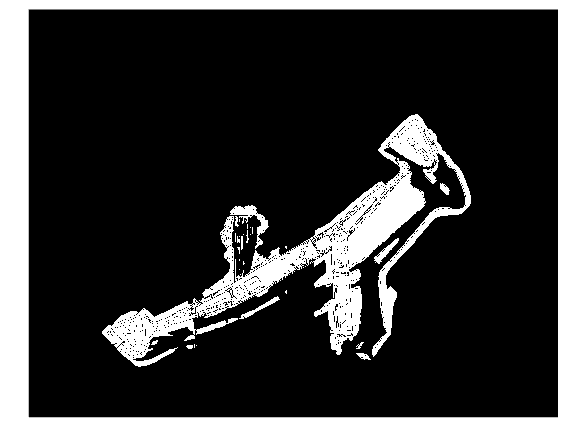

imshow(~total & areaOfIntrest);

#### 3.3.2) checker mask

A checker pattern was introduced and ANDed with the Area of Interest. The idea was to add these points to the valid points as a way to "seed" new areas that were previously overlooked.

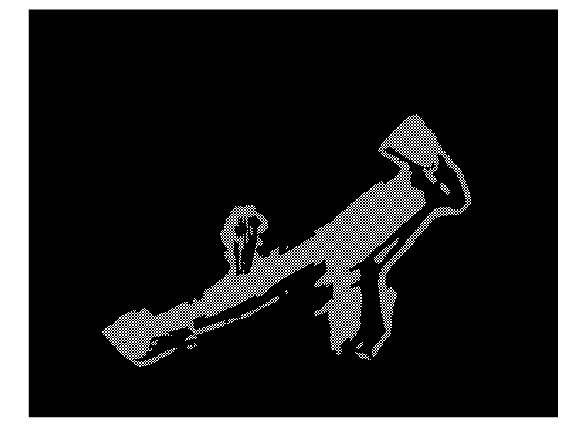

squareSize = 6;
[maskHeight, maskWidth] = size(areaOfIntrest); % Size of the existing mask

checkerPattern = checkerboard(squareSize, ceil(maskHeight / (2 * squareSize)), ...
                          ceil(maskWidth / (2 * squareSize)));
checkerMask = checkerPattern > 0.5;
checkerMask = checkerMask(1:maskHeight, 1:maskWidth);
areaOfIntrestcheckerMask = areaOfIntrest & checkerMask;

imshow(areaOfIntrestcheckerMask);

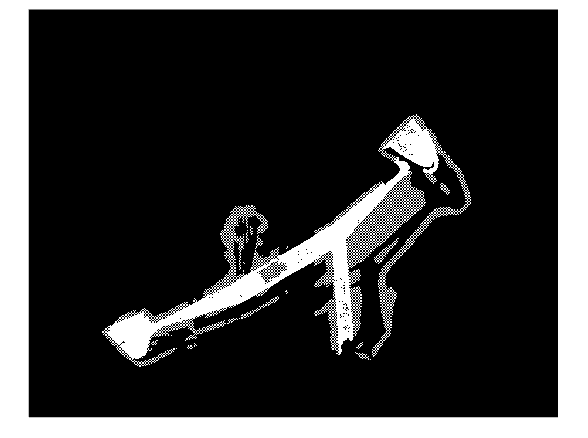

%these points get then temporaly added to the list of tracking points
validNewPointsBinaryMask = validNewPointsBinaryMask | areaOfIntrestcheckerMask;
imshow(validNewPointsBinaryMask);

#### 3.3.3) cleaning up edges

After detecting edges, we observed that poor lighting conditions often caused excessive noise along edges, with clusters of points forming near the borders of the detected regions. To address this, we implemented a method to clean up the edge mask by introducing a hollow diamond-shaped structural element. This approach helps to simplify the edges, reduce clutter, and ensure the mask represents a more realistic boundary.

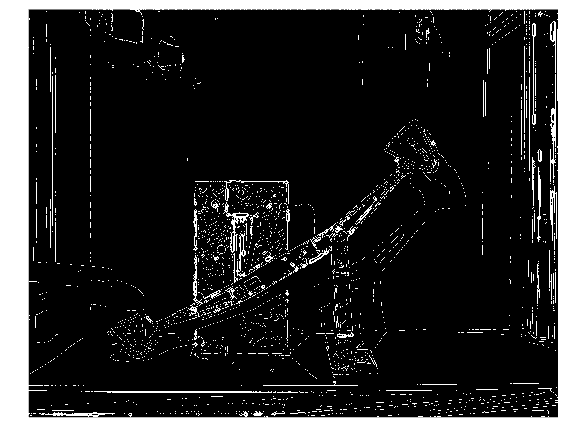

% Define the structural element
se = strel('diamond', 7);
% Get the binary mask of the structural element
seMask = se.Neighborhood; % Structural element as binary mask
% Create the hollow (outline) version of the structural element
hollowSE = seMask & ~imerode(seMask, strel('disk', 1));
% Calculate the number of pixels in the structural element
numPixelsInSE = sum(seMask(:));
% Convolve the input mask with the structural element
localSum = conv2(double(total), double(seMask), 'same');
% Calculate the percentage of white pixels in the neighborhood
percentage = localSum / numPixelsInSE;
% Find areas where 50% or more of the pixels are white
thresholdMask = (percentage >= 0.5);
% Get the indices of the pixels affected by the structural element
[rows, cols] = find(thresholdMask);
% Initialize lists for pixels to be set to 1 or 0
needToBeOne = false(size(total));
needToBeZero = false(size(total));
% Create offsets for the hollow structural element
[offsetRows, offsetCols] = find(hollowSE);
centerOffset = floor(size(hollowSE) / 2);
% Loop through each affected position and add indices
for k = 1:length(rows)
    % Calculate the positions for the structural element
    rowOffset = rows(k) - centerOffset(1);
    colOffset = cols(k) - centerOffset(2);
    % Apply offsets for hollow region
    hollowRowIndices = rowOffset + offsetRows;
    hollowColIndices = colOffset + offsetCols;
    % Ensure indices are within bounds
    validIndices = hollowRowIndices > 0 & hollowColIndices > 0 & ...
                   hollowRowIndices <= size(total, 1) & hollowColIndices <= size(total, 2);
    hollowRowIndices = hollowRowIndices(validIndices);
    hollowColIndices = hollowColIndices(validIndices);
    % Update masks
    linearIndices = sub2ind(size(total), hollowRowIndices, hollowColIndices);
    needToBeOne(linearIndices) = true;
    needToBeZero(rows(k), cols(k)) = true; % Center pixel is cleared
end
% Update the result
result = total;
result(needToBeOne) = 1;
result(needToBeZero) = 0;

imshow(result);

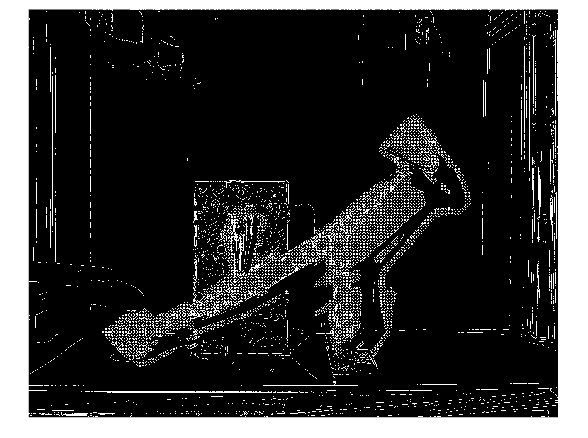


thinedTotalResult = bwmorph(result, 'remove') | bwmorph(areaOfIntrestcheckerMask, 'remove'); %a hallow version of the checker mask is added, also in an attempt to help close open bordereds.
imshow(thinedTotalResult);

#### 3.3.4) stars

Applied a "star" dilation pattern at endpoints of disconnected edges to bridge gaps and reconnect regions that edge detection failed to close. This approach aimed to create contiguous regions that could hold points.

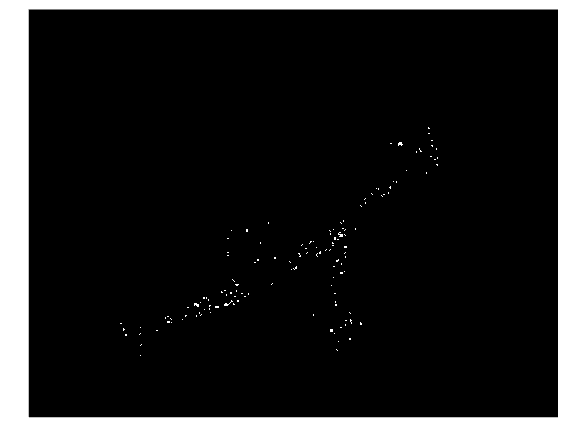

%preparing the mask
thick = bwmorph(validNewPointsBinaryMask, 'thicken');
brigdeClose = bwmorph(thick, 'close');
bridged = bwmorph(brigdeClose, 'bridge');
bridged(thinedTotalResult == 1) = 0;

%actualy doing the stars
neighborhoodKernel = ones(3, 3); 
neighborhoodKernel(2, 2) = 0;
neighborCount = conv2(~bridged, neighborhoodKernel, 'same');
dots = (~bridged == 1) & (neighborCount <= 1);

%dots = filter_large_areas(ends, 1); % trying to get rid of area's if
%they are to close togater

%making the star shape
starLength = 9;
horizontal =    center_in_matrix(getnhood(strel("line",starLength,0)), starLength);
vertical =      center_in_matrix(getnhood(strel("line",starLength,90)), starLength);
leftleaning =   center_in_matrix(getnhood(strel("line",starLength * sqrt(2),45)), starLength);
rightleaning =  center_in_matrix(getnhood(strel("line",starLength * sqrt(2),-45)), starLength);

star = horizontal | vertical | leftleaning | rightleaning;

% adding the stars
stars = imdilate(dots, star);
imshow(stars);


%getting rid of to large areas
smallStars = filter_large_areas(stars, 200);

%make a copy for easy debugging
addedStars = bridged;

addedStars(smallStars == 1) = 0

addedStars = 1726×2240 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   

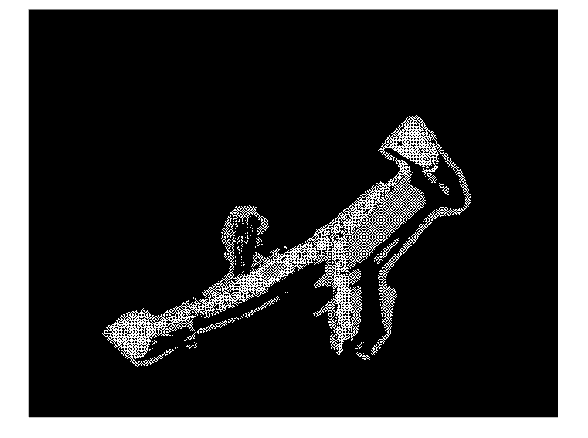


imshow(addedStars);

#### 3.3.4) find the erea's with points in them

We then look for places where the points and the area overlap and add back the points we assumed to have lost.

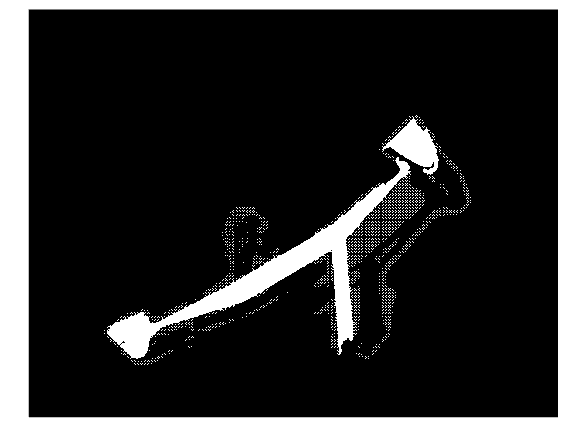

%% some prep work before we start before we 
openUp = imopen(bridged, [1 1; 1 1]);
[labeledMask, numAreas] = bwlabel(openUp, 4);

%filled masked with valid trecking points
filledValidPoinst = imfill(validNewPointsBinaryMask, 'holes'); % validNewPointsBinaryMask from line 153
    
%get rid of stray lines
openUpValidPonits = imopen(filledValidPoinst, [1 1; 1 1]);

%% start finding the area's.
[col, row] = find(openUpValidPonits);
eraPoints = [row, col];

validPointsIndices = sub2ind(size(frame), round(eraPoints(:, 2)), round(eraPoints(:, 1))); % Convert points to linear indices
areasWithPoints = unique(labeledMask(validPointsIndices)); % Get unique area labels with points
    
areasWithPoints(areasWithPoints == 0) = []; %don't want zero's
finalMask = ismember(labeledMask, areasWithPoints);

[row, col] = find(finalMask);
pointsList = [col, row];

combined = [validNewPoints; pointsList];

%% we return this back into mask
combinedMask = false(size(frame)); % Initialize a binary mask of the same size as the frame

rows = round(combined(:, 2)); % Y-coordinates 
cols = round(combined(:, 1)); % X-coordinates 

% Set the corresponding locations in the mask to true
combinedMask(sub2ind(size(combinedMask), rows, cols)) = true;

%% get rid of any points that fall out of the area of intrest.
combinedMaskAndAreaOfIntrest = combinedMask & areaOfIntrest; % take only the parts insisde of the Area of Intrest
filledUpCombo = imfill(combinedMaskAndAreaOfIntrest, 'holes');

%clean it up a little
openComboMask = imopen(filledUpCombo, [1 1; 1 1]); %get rid of stray lines
lastMask = imclose(openComboMask, [1 1; 1 1]);

imshow(lastMask);

### 3.4) prevent infinite growth

To prevent unchecked growth of regenerated points, we imposed a strict constraint: the total area of tracked points was capped at 95% of the initial mask's area. Any excess points were iteratively reduced using morphological operations to maintain consistency. Without this constraint, the results can become problematic, as shown here

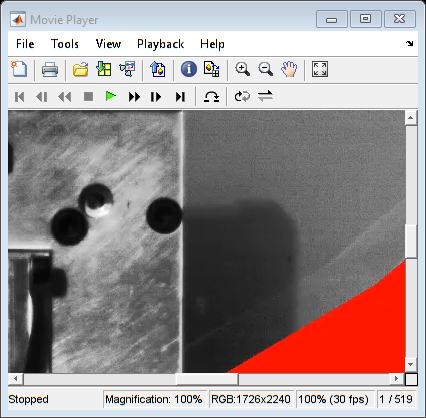

implay("Videos\infGrowth.mp4", 30);

This is the code to prevent that.

% code that would run before the main loop
image_gray = imread('cutout.png');
binaryImage = imbinarize(image_gray, 0.1);
[y, x] = find(binaryImage);
[totalArea, ~] = size(y);
totalArea = totalArea * 0.95;

%in the main loop
currentArea = nnz(lastMask); % Count the number of non-zero (true) pixels

while currentArea > totalArea
    lastMask = bwmorph(lastMask, 'thin', 1);
    
    currentArea = nnz(lastMask);
    fprintf('Current area: %d, Target area: %d\n', currentArea, totalArea);
end

Current area: 175786, Target area: 1.704309e+05
Current area: 164846, Target area: 1.704309e+05


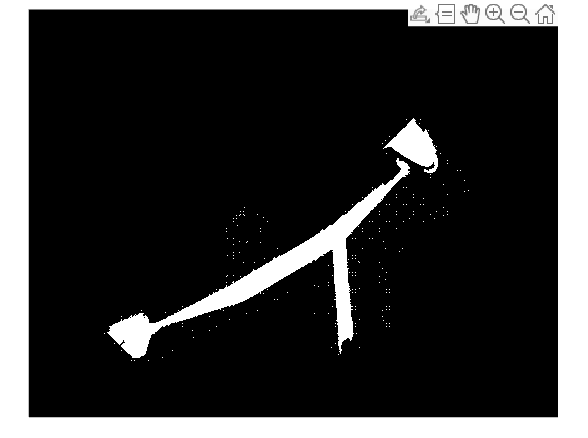


imshow(lastMask);

This mask is converted back into points and used in the tracker.

[row, col] = find(lastMask);
finalPoints = [col, row];

%and then add the points. This will give an error in this live script cause
%we haven't created a tracker object. But it's the same deal as in line 14.
tracker.setPoints(finalPoints); %will

Unable to resolve the name 'tracker.setPoints'.

## 4) conculsion

While the project did not achieve the desired results entirely, significant progress was made in tracking the object under challenging conditions. The given video presented numerous issues, including:

- Flickering lights.

- Moving shadows of the machine on the back wall

- Moving reflections of the machine on the back wall

- The back wall’s color similarity to the machine

AI tools or a more experienced image processing expert might achieve better results. For future videos, the following recommendations can help mitigate these challenges:

- To prevent flickering, try matching the camera's speed with the lamps. A multiple of 50 Hz would likely resolve this issue. Instead of 380 fps, try 400 or 350 fps, if possible.

- If changing the frame rate isn’t an option, consider using lamps that don’t flicker. Affordable DC-powered lamps are available that can eliminate flickering.

- Place the lamps above the machine so that the shadows fall on the ground instead of the back wall.

- Attach a white piece of cloth to the back wall to reduce reflections and improve contrast.

- Add black tape to the edges of the machine, or paint it entirely black if feasible, to make it more distinct from the background.

I also wish I could have worked with a more structured approach. The long rendering times and the short deadline during the busiest time of the semester didn’t allow me to take things slower, so I could think through what I was doing more carefully. I just tried to do everything I could think of within the timeframe I was given.

here are some of the best attempts:

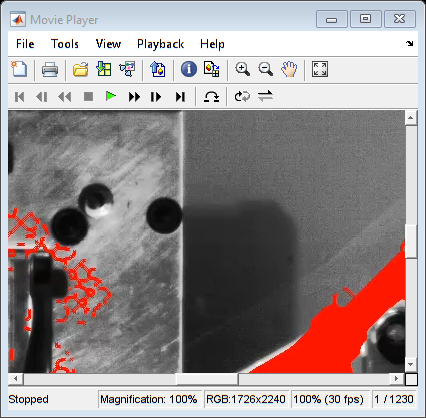

implay("Videos\20241224_152240.mp4", 30);
implay("Videos\20241224_024126.mp4", 30);

You can go to the google drive and sort by date to see the progression. Thing should still be in the right order there. I did have to recreate some video's at the end, so the last few vids might of older version, but there names are very clear. 